# Example: Color tracking calibration

The AR Drone 2.0 has two cameras, in this example we will use the front facing camera to track objects of a specific color.

## The calibration model

A model is included with the AR Drone 2.0 toolbox which you can use to determine the parameters for your object.

    1.    Open the color calibration model by evaluating:

Calibrating_The_AR_Drone_Camera_Model

This will open the following model:

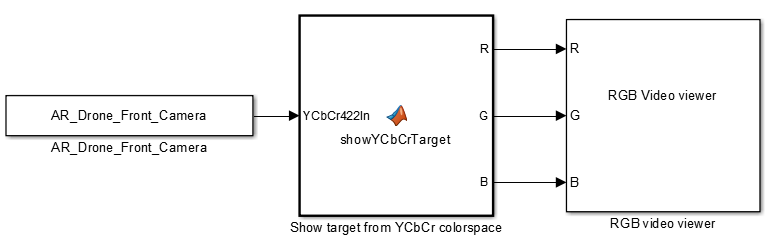

    2.    **Build** the model

    3.    **Connect to target **to connect to the AR Drone 2.0

    4.    **Run **the model on the AR Drone 2.0. A figure will open showing you a modified front camera video feed. Black pixels fall outside of the specified color tracking range, white pixels are inside the color tracking range. The red pixel indicates the centre of the tracked pixels.

    5.    **Tune **your color tracking parameters in the **showYCbCrTarget** block. Tune such that only the object you wish to tracks is shown as white pixels.

    6.    When ready, **Stop** the model.

    7.    You can save the parameters by pressing the **save parameters** button inside the **showYCbCrTarget** block.

# Color calibration model background

In this model we see three blocks:

## **Ar_Drone_Front_Camera:**

This block retrieves images from the front camera. These images are in the YCbCr image format and have a 1280x720 resolution. The YCbCr color space is explained below.

## **Show target from YCbCr colorspace:**

This block down samples the incoming video feed and then determines which pixels lie within the user defined sub space of the YCbCr color space. Click on this block to select what range of the YCbCr color space should be used. The **YCbCr color space** chapter below explains how you should choose your parameters.

The outputs of this block indicate which pixels fell within the user selected color sub space. The centre of all the tracked pixels is indicated with a red dot. Note that some noise can be present, showing floating pixels. If there is relatively little noise compared to the amount of pixels deteced from the actual target, the target position will be computed relatively accurately despite the noise. When the target is missing, false positives could occur due to noise. To guard against this you can increase the minimum amount of pixels that should lie within the color sub space before a target is detected.

## **RGB video viewer**

The RGB viewer block takes three input matrixes of 8 bit unsigned integers and outputs them as an RGB image in MATLAB. In this case black parts of the image did not satisfy the defined YCbCr sub space while white pixels did, the red pixel indicates the centre of all pixels that fell inside the user defined YCbCr color sub space.

# Using the parameters:

The color tracking parameters are saved in the **ArDroneDataDictionary**. Using the **load parameters **and **save parameters** buttons in these blocks allows you to load or save the current parameters to and from the data dictionary. Some example values for parameters can be seen below in the **Examples** section.

When you have tuned the parameters you can use them in the **Object tracking** block located in:

AR_Drone_Video_Processing

The **Object tracker **block shown below uses the same parameters as the calibration model. This block is used in the green ball tracking demo. Documentation for this demo model is provided in the **Tracking demo **section of the documentation.

To reduce overhead this block only outputs the location of the mean position, identical to the red dot in the calibration model. It outputs the flag: '1' if the amount of detected target pixels passes the user defined threshold. If not enough pixels match the target color the flag will be '0'. The tarrgetOffsetX/Y outputs of the **Object tracking **block are scaled between (-1, 1) for both axes. An output of '0' for both the target offsets means the target average is in the centre of the camera.

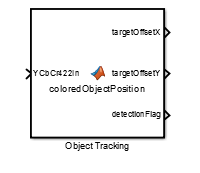

# The YCbCr color space:

The default output format of the AR Drone cameras is very usefull for color based object detection as the luminesce (Y in YCbCr) is decoupled from the color data (Cb and Cr in YCbCr). This means that the color information is relatively lighting independent (note that the cameras do auto adjust their white balance for different ambient light conditions meaning that color detection is still somewhat dependent on lighting conditions). The below image shows the YCbCr color space for a luminesce of 50%.

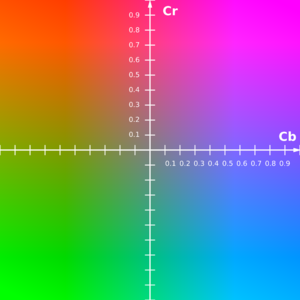

In the image the values of the red shift (Cr) and blue shift(Cb) are shown in the range (-1, 1). The camera of the AR Drone 2.0 uses unsigned 8 bit integers to represent the color data meaning that the range (-1, 1) of the above image is mapped to integers of (0, 255) on the AR Drone 2.0. By selecting the minium and maximum desired red and blue shift values in the **Show target from YCbCr colorspace **MATLAB function block mask we can determine which colors are detected.

# Examples:

## Finding a red button

The drone was given the goal to detect the position of the red 'easy' button show below:

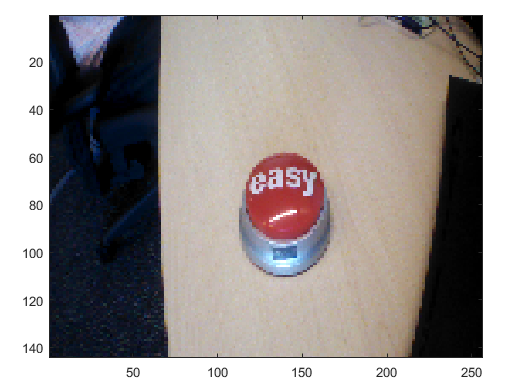

For this the following settings were used:

- Video input width, height, down sample factor = 1280, 720, 5

- Blue shift min,max = 0, 150

- Red shift min,max = 160, 225

- Minimum object detection pixel count = 10;

This resulted in the following view:

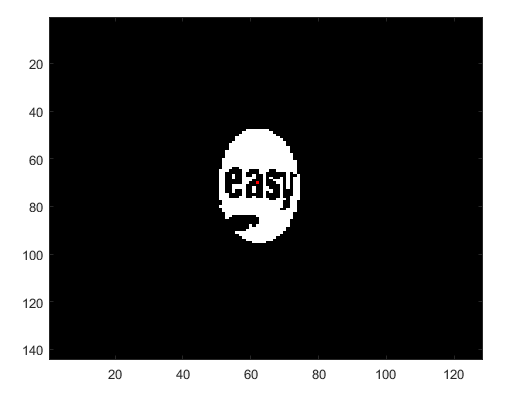

## Finding a green ball

The drone was given the goal to detect the position of the green ball shown below:

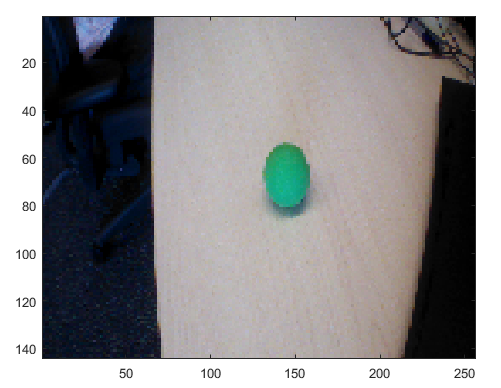

For this the following settings were used:

- Video input width, height, downsample factor = 1280, 720, 5

- Blue shift min,max = 0, 122

- Red shift min,max = 0, 122

- Minimum object detection pixel count = 10;

This resulted in the following view: